# Thermal Noise

Author: Aaron Kaw

Date: 31/3/2021

## Configuration

MATLAB Version: 9.8.0.1396136 (R2020a) Update 3

Operating System: Microsoft Windows 10 Enterprise Version 10.0 (Build 19042)

Java Version: Java 1.8.0_202-b08 with Oracle Corporation Java HotSpot(TM) 64-Bit Server VM mixed mode

## References

[1] Readhead, M. L. (2014, October). Is underwater thermal noise useful?. In *Inter-Noise and Noise-Con Congress and Conference Proceedings* (Vol. 249, No. 2, pp. 4978-4983). Institute of Noise Control Engineering.

## Usage & Examples

The purpose of this MATLAB live script is to demonstrate the use of the `thermalnoise` function.

### Built-In

The MATLAB implementation has some built-in examples. Run the function without arguments.

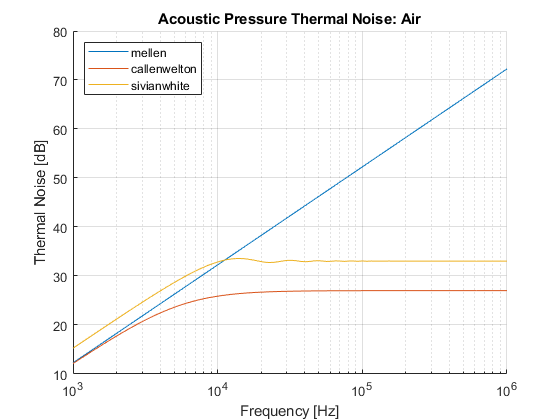

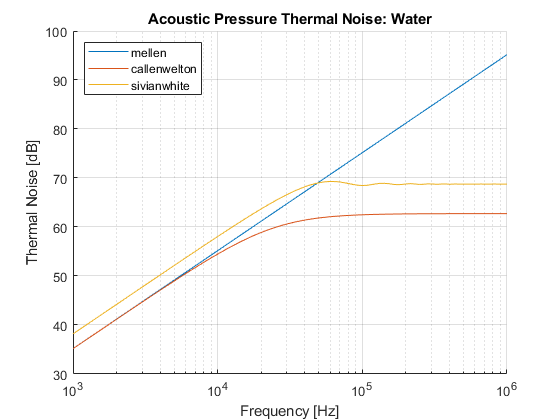

thermalnoise

### Mellen (Point) & Callen-Welton (Vanishing Sphere)

Callen & Welton's formula for acoustic pressure thermal noise was developed for a vanishing sphere. Mellen computed acoustic pressure thermal noise for a point, and found a formula equivalent to Callen & Welton's.


$$\left\langle P^2 \right\rangle df=\frac{4\pi k_B T\rho \;f^2 }{c}df$$


Callen & Welton's vanishing sphere has been omitted from the implementation due to superfluity.

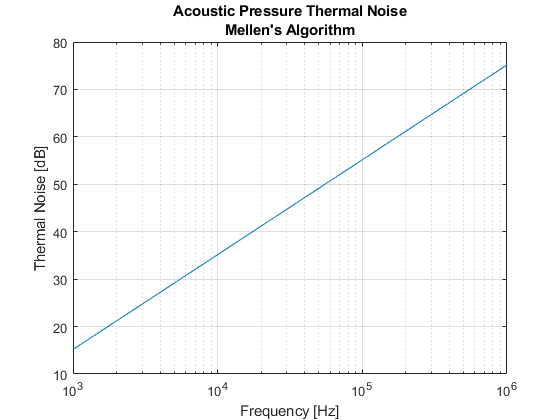

rho = 1027.3;
c = 1500;
T = 4 + 273.15;
f = 10.^(linspace(log10(1e3), log10(1000e3)));
df = 1e3;

method = 'Mellen';
tn = thermalnoise(method, T, rho, c, f, df);

figure
plot(f, tn)
grid on
set(gca, 'xscale', 'log')
xlabel('Frequency [Hz]')
ylabel('Thermal Noise [dB]')
title({'Acoustic Pressure Thermal Noise', [method '''s Algorithm']})

### Callen-Welton (Sphere)

Callen & Welton also derived thermal noise over the surface of a sphere. This demands an additional parameter of spherical radius `a`.


$$\left\langle P^2 \right\rangle df=\frac{4\pi k_B T\rho \;f^2 }{\left(1+{\left(ka\right)}^2 \right)c}df$$


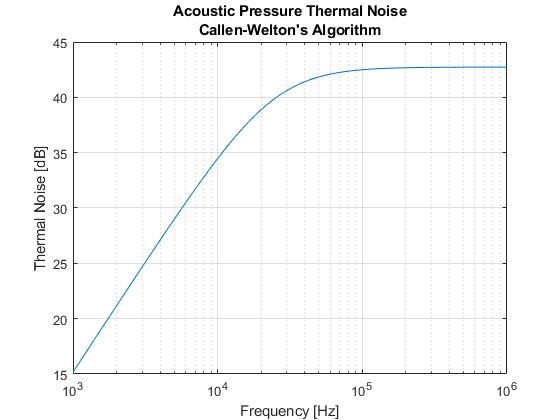

rho = 1027.3;
c = 1500;
T = 4 + 273.15;
f = 10.^(linspace(log10(1e3), log10(1000e3)));
df = 1e3;
a = 1e-2;

method = 'Callen-Welton';
tn = thermalnoise(method, T, rho, c, f, df, a);

figure
plot(f, tn)
grid on
set(gca, 'xscale', 'log')
xlabel('Frequency [Hz]')
ylabel('Thermal Noise [dB]')
title({'Acoustic Pressure Thermal Noise', [method '''s Algorithm']})

### Sivian-White (Piston)

The Sivian-White algorithm calculates the thermal acoustic pressure averaged over a piston in infinite wall. This time the radius `a` is of the piston.


$$\left\langle P^2 \right\rangle df=\frac{4k_{B\;} T\rho \;c}{\pi a^2 }\left(1-\frac{J_1 \left(2\mathrm{ka}\right)}{\mathrm{ka}}\right)$$


where $J_1$ is the first Bessel function of the first kind.

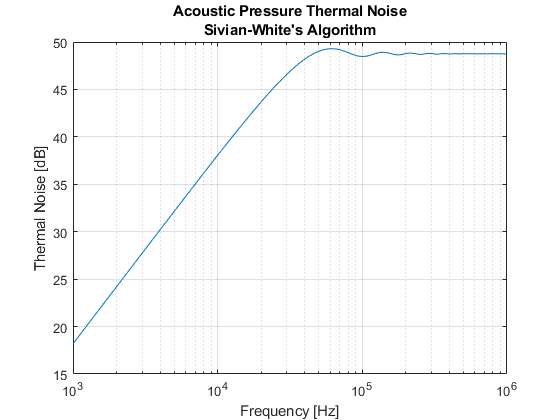

rho = 1027.3;
c = 1500;
T = 4 + 273.15;
f = 10.^(linspace(log10(1e3), log10(1000e3)));
df = 1e3;
a = 1e-2;

method = 'Sivian-White';
tn = thermalnoise(method, T, rho, c, f, df, a);

figure
plot(f, tn)
grid on
set(gca, 'xscale', 'log')
xlabel('Frequency [Hz]')
ylabel('Thermal Noise [dB]')
title({'Acoustic Pressure Thermal Noise', [method '''s Algorithm']})

### Comparing

The MATLAB implementation allows the comparison of multiple algorithms. Suppose we want to compare Sivian-White's piston algorithm with Callen-Welton's spherical surface algorithm. Note that the function output is now a struct with fieldnames of the algorithms in lowercase letters only.

Alternatively of course, `thermalnoise` can be called for each individual algorithm.

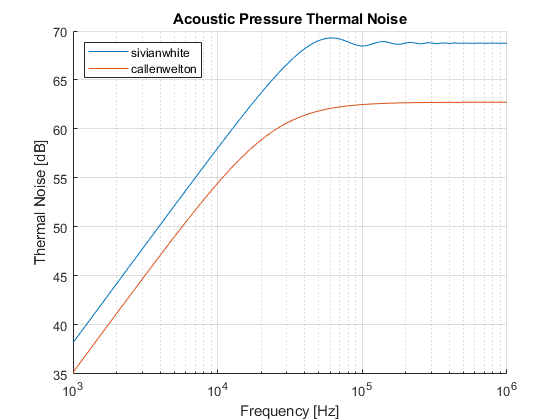

rho = 1027.3;
c = 1500;
T = 4 + 273.15;
f = 10.^(linspace(log10(1e3), log10(1000e3)));
df = 1e5;
a = 1e-2;

methods = {'Sivian-White', 'Callen-Welton'};
tn = thermalnoise(methods, T, rho, c, f, df, a);

figure
hold on
for method = fields(tn)'
	m = method{:};
	plot( ...
		f, tn.(m), ...
		'DisplayName', m ...
		)
end
legend('Location', 'NorthWest')
title('Acoustic Pressure Thermal Noise')
xlabel('Frequency [Hz]')
ylabel('Thermal Noise [dB]')
set(gca, 'xscale', 'log')
grid on